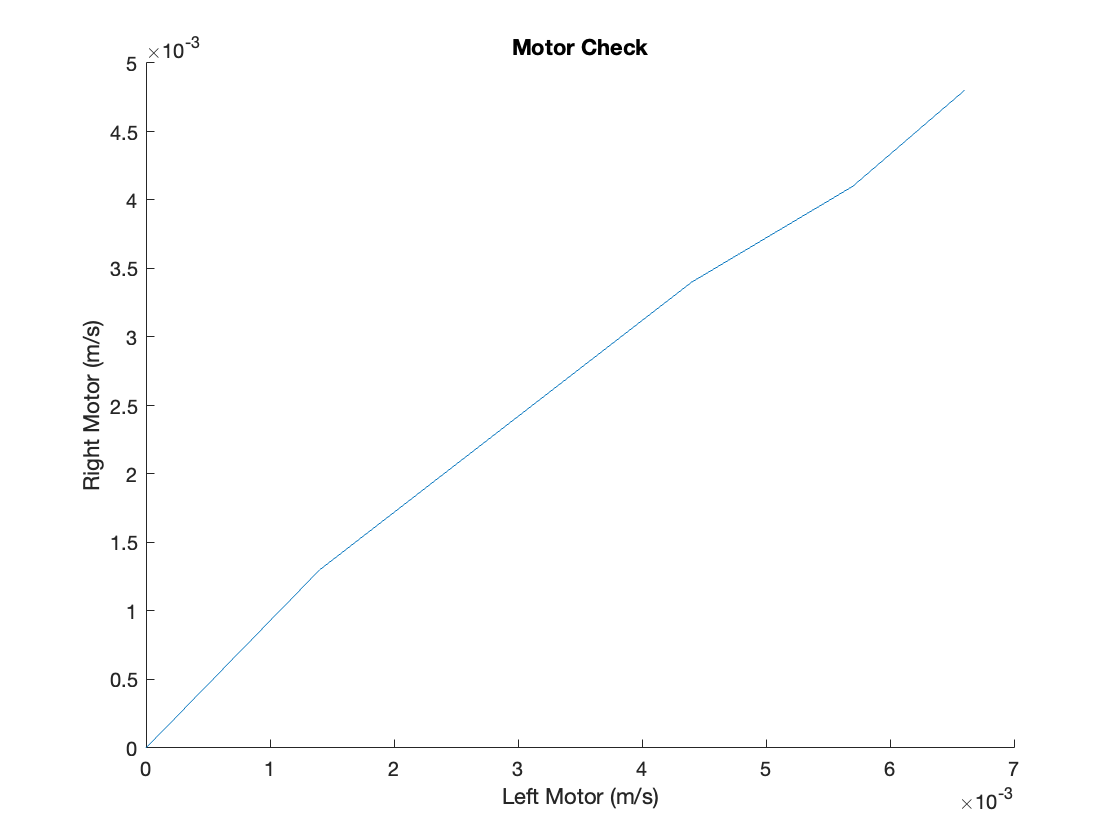

% Checking if motors have same speed

clear
clf
load Data/calibration_first_run.mat

sample_limit = 5;                                               % Max limit of valid data
left_motor = calibration_first_run(1:sample_limit,1) / 100;
right_motor = calibration_first_run(1:sample_limit,2) / 100;

hold on 
title("Motor Check")
xlabel("Left Motor (m/s)")
ylabel("Right Motor (m/s)")
plot(left_motor, right_motor)
hold off 


p = polyfit(left_motor, right_motor, 1);
 
cali_cruve_slope = p(1);
cali_cruve_y_intercept = p(2);

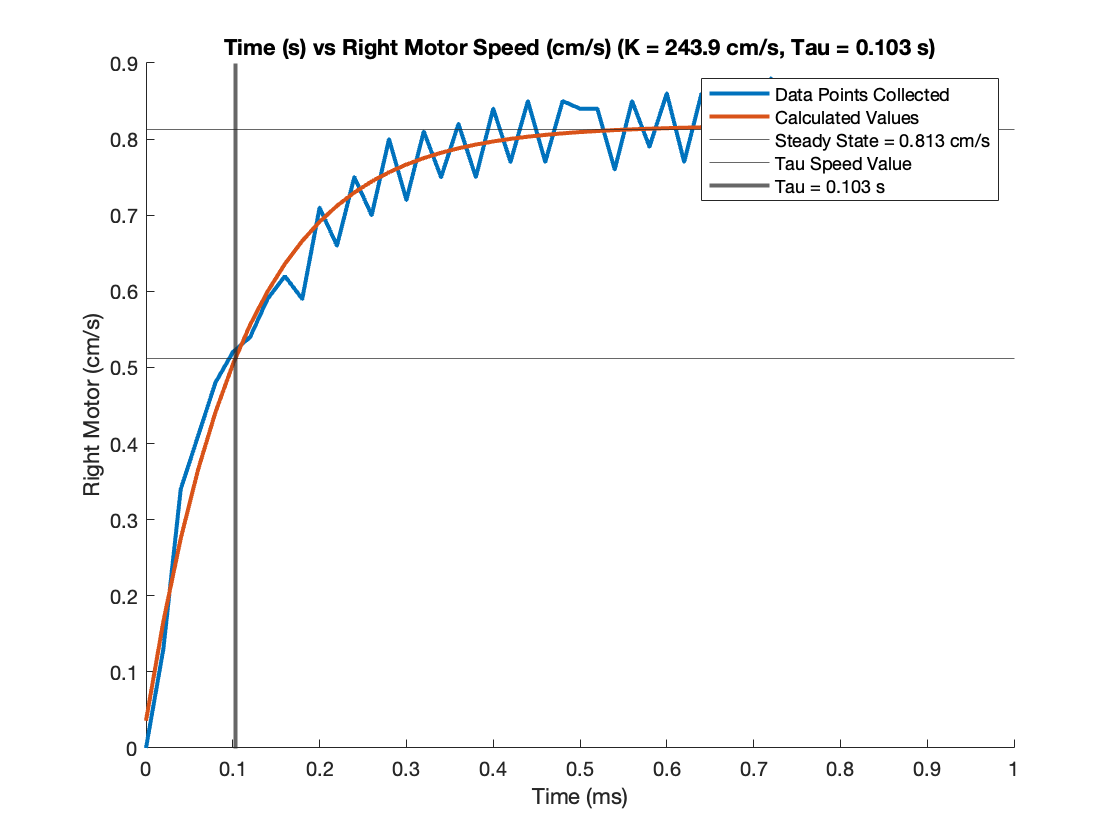

% Part A
clf

% Finding K/Tau
time_sample = 50;
time_interval = [0:20:(20*(time_sample-1))]' / 1000;
right_motor = calibration_first_run(1:time_sample,2);

% Cftool values (R-Sqaured = 0.9512)
a = 0.8156;
b = 0.004005;
c = -0.7798;
d = -9.159;

calc_right_motor = a*exp(b*time_interval) + c*exp(d*time_interval);

right_motor_steady_state = 0.813;                                          % Found using Cftool
tau_speed_value = 0.813 * 0.63;
tau = 0.103         ;                                                      % Found graphically
motor_input = 300;
K = motor_input * right_motor_steady_state;                                % 243.9               

hold on
title("Time (s) vs Right Motor Speed (cm/s) (K = 243.9 cm/s, Tau = 0.103 s)")
xlabel("Time (ms)")
ylabel("Right Motor (cm/s)")
plot(time_interval, right_motor, "LineWidth", 2)
plot(time_interval, calc_right_motor, "LineWidth", 2)
yline(right_motor_steady_state)
yline(tau_speed_value)
xline(tau, "LineWidth", 2)
legend("Data Points Collected", "Calculated Values", "Steady State = 0.813 cm/s", "Tau Speed Value" , "Tau = 0.103 s")
hold off